# **JacobiDN**

Jacobi elliptic function dn

## Definition


$$\mathrm{dn}\left(x\left|m\right.\right)\equiv \sqrt{1-m\;{\mathrm{sin}}^2 \left(\mathrm{am}\left(x|m\right)\right)}$$



$$\mathrm{dn}\left(x,k\right)\equiv \mathrm{dn}\left(x|k^2 \right)$$


where *am* is Jacobi amplitude function, $-\infty <x<\infty$, $-\infty <m<\infty$ is the parameter and $\left|-\infty <k<\infty \right.$ is the modulus. For the specified domain, the  codomain of *dn *are real numbers.

Basic features:

$\mathrm{dn}\left(x+2K\left|m\right.\right)=\mathrm{dn}\left(x\left|m\right.\right)$  (periodic) ,  $\mathrm{dn}\left(-x\left|m\right.\right)=\mathrm{dn}\left(x\left|m\right.\right)$ (even)

Special values:


$$\mathrm{dn}\left(0\left|m\right.\right)=1$$


$\mathrm{dn}\left(x|0\right)=1$,  $\mathrm{dn}\left(x|1\right)=\mathrm{sech}\left(x\right)$

## Syntax

Y = JacobiDN(X,K)

y = jdn(x,k)

Y = mJacobiDN(X,M)

y = mjdn(x,m)

## Description

Y = JacobiDN(X,K) returns the Jacobi elliptic function $\mathrm{dn}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. JacobiDN is the wrapper function which calls the functions **jdn** element-wise via the function **ufun2**.

y = jdn(x,k) returns the Jacobi elliptic function $\mathrm{cn}\left(x,k\right)$ for argument x and the modulus k. It is assumed that  arguments are real scalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed. **jdn** calls the functions **sncndn **for calculation of *dn *.

Y = mJacobiDN(X,M) returns the Jacobi elliptic function $\mathrm{dn}\left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. mJacobiDN is the wrapper function which calls the function **mjdn** element-wise via the function **ufun2**.

y = mjdn(x,m) returns the Jacobi elliptic function $\mathrm{dn}\left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that  arguments are real scalars without check. The function returns NaN if either of  the arguments is invalid or convergence failed.  **mjdn** calls the functions **sncndn **for calculation of *dn *.

**sncndn **implements the AGM transformation for simultaneously  computation of the functions *sn*, *cn*, *dn* . For $m>1$ the Jacobi's transformation is used [1,2].

## Precision

For  $|m|\le 1$ the relative error of $\mathrm{dn}\left(x\left|m\right.\right)$ is less than ${10}^{-12}$ when $|x|<{10}^4$. For  $\left|m\right|\le {10}^4$ the relative error of $\mathrm{dn}\left(x\left|m\right.\right)$ is less than ${10}^{-10}$ when $|x|<{10}^4$.

## **Numerical Examples**

**Salar input**

jdn(2,1)

ans = 0.2658

mjdn(2,1)

ans = 0.2658

fprintf('%.16g\n',mjdn(3,5))

0.9975720595366809


*Note*. Exact value dn(3|5) =  `0.997572059536680``99`

**Vector of function values**

Create a column vector of domain values

x = (0:0.2:1)'

x =                    0
   0.200000000000000
   0.400000000000000
   0.600000000000000
   0.800000000000000
   1.000000000000000


Calculate the function values with k = 0.5

JacobiDN(x,0.5)

ans =    1.000000000000000
   0.995070236941089
   0.981096091447875
   0.960329761812670
   0.935960103275983
   0.911492005669132


Create a row vector of parameter values

m = -1.5:0.5:1

m =   -1.500000000000000  -1.000000000000000  -0.500000000000000                   0   0.500000000000000   1.000000000000000


Calculate the function values at x = 0.5

mJacobiDN(0.5,m)

ans =    1.176249708641312   1.116647148886487   1.057894277400903   1.000000000000000   0.942972425777386   0.886818883970074


Calculate the function values for two array arguments

mJacobiDN([2 1 -3],[1 2 3])

ans =    0.265802228834080   0.310737930333856  -0.004570930199922


mJacobiDN([2 1 -3]',[1 2 3]')

ans =    0.265802228834080
   0.310737930333856
  -0.004570930199922


**Matrix of function values**

Create a matrix of domain values

X=[-1 0 1 2; 2 3 4 8];

Calculate the function values with parameter m = 2.

mJacobiDN(X,2)

ans =    0.310737930333856   1.000000000000000   0.310737930333856  -0.673733198974534
  -0.673733198974534  -0.866554151847649   0.066913534417134  -0.982248917924415


Calculate the function values for two matrix arguments.

JacobiDN([2 1 -3; -1 2 3],[1 2 3; -1 2 3])

ans =    0.265802228834080  -0.269864965451087  -0.765825363328756
   0.648054273663885  -0.814473953523499  -0.765825363328756


## **Graphs **

**Example 1**

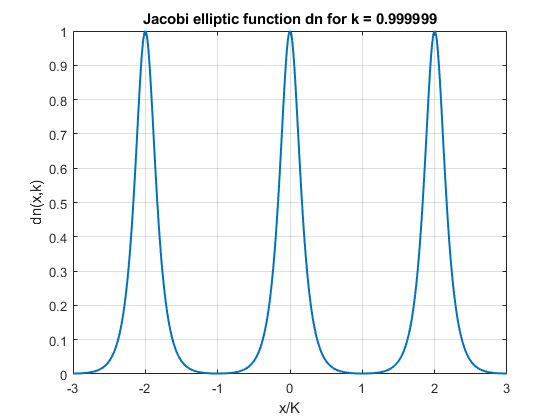

figure
x=-3:0.01:3;
k = 0.999999;
plot(x,JacobiDN(elK(k)*x,k),'LineWidth',1.5)
xlabel('x/K')
ylabel('dn(x,k)')
title(sprintf('Jacobi elliptic function dn for k = %g',k))
grid on

**Example 2**

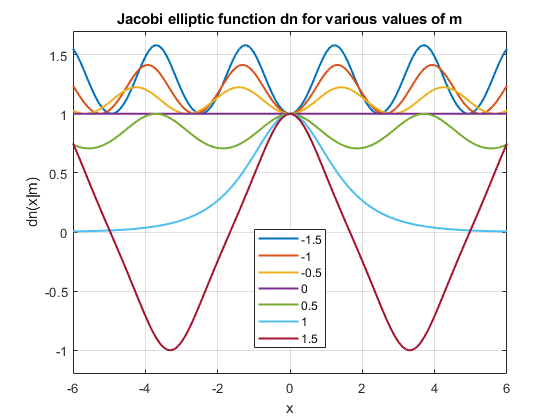

figure
X = -6:0.1:6;
M = -1.5:0.5:1.5;
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mJacobiDN(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) -1.2 1.7])
grid on
legend(clg,'Location','Best')
title('Jacobi elliptic function dn for various values of m')
xlabel('x')
ylabel('dn(x|m)')

**Example 3**

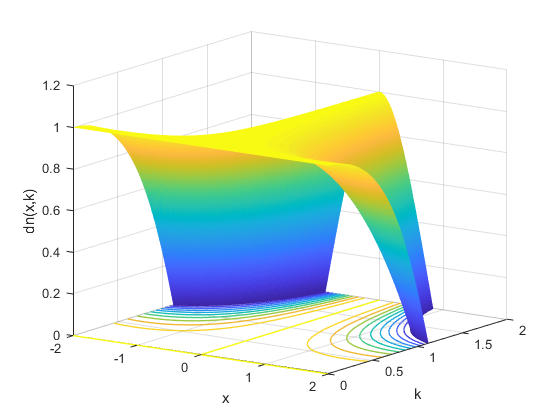

figure
x=-2:0.01:2;
k=0:0.01:2;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,JacobiDN(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 1;
hc.LevelList = 0:0.1:1;
caxis([0 1])
view([35 15]);
xlabel('x')
ylabel('k')
zlabel('dn(x,k)')
zlim([0 1.2])
grid on

**Example 4**

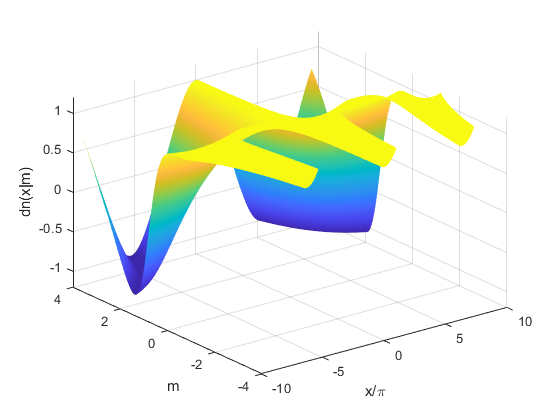

figure
x=-3:0.01:3;
m=-4:0.01:4;
[X,M]=meshgrid(x,m);
surface(pi*X,M,mJacobiDN(X,M),'EdgeColor','none')
view(3)
caxis([-1 1])
xlabel('x/\pi')
ylabel('m')
zlabel('dn(x|m)')
zlim([-1.2 1.2])
grid on

**Example 5**

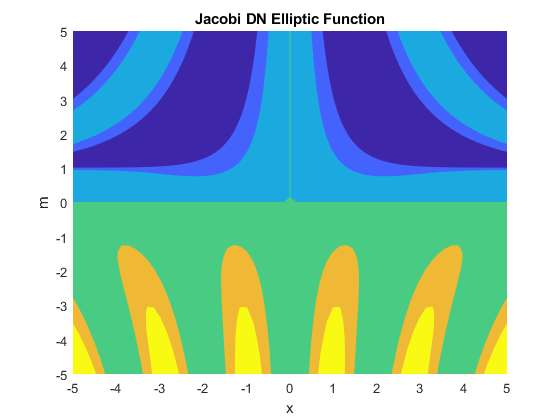

figure
f = @(x,m)mJacobiDN(x,m);
fcontour(f,'Fill','on')
title('Jacobi DN Elliptic Function')
xlabel('x')
ylabel('m')

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] R. Bulirsch, Numerical Calculation of Elliptic Integrals and Elliptic Functions. Numerische Mathematik 7, 78-90, 1965

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also